# Лабораторная работа №5

Решение задачи Коши для обыкновенных дифференциальных уравнений методом Рунге-Кутты 3-го порядка.

ДУ:  $y\prime -\frac{y{\left(2x-5\right)}}{x^2 }=5$ 

Задача Коши: $y{\left(2\right)}=4$ $x\in {\left[2;6\right]}$

Входные данные:

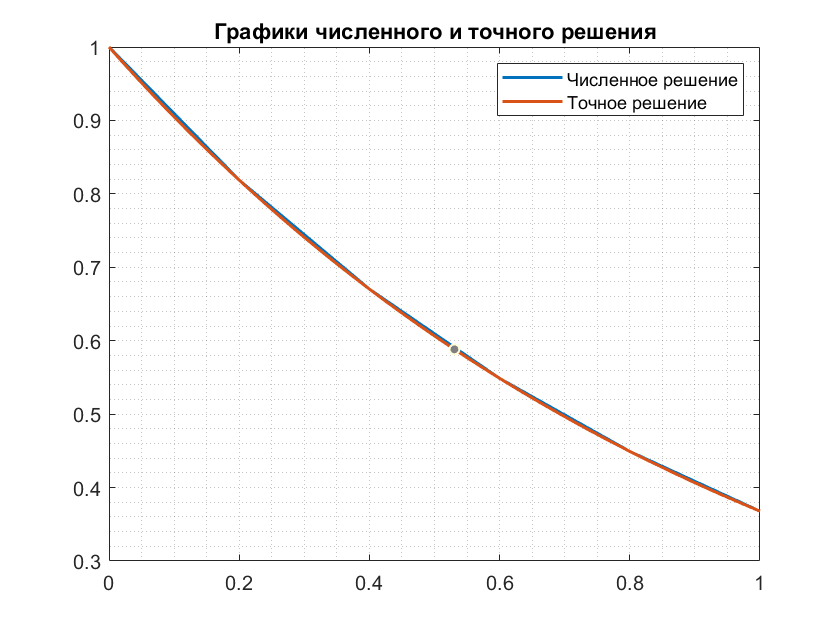

% f = @(x, y) 5 + (y*(2*x-5))/(x.^2);
f = @(x, y) -y; %для теста
a = 0;
b = 1;
n = 5;
y_2 = 1;
[x, y] = runge_kuta(f, a, b, n, y_2);
x1 = linspace(a, b, 50);
y1 = exp(-x1);
figure
plot(x, y, 'LineWidth', 1.5)
hold on
plot(x1, y1, 'LineWidth', 1.5)
grid minor;
title('Графики численного и точного решения')
legend('Численное решение', 'Точное решение')

disp(max(abs(y - y1)))

Matrix dimensions must agree.

Построение зависимости погрешности метода от шага:

nmax = 1000;
 

f = @(x,y) 5 + (y*(2*x-5))/(x.^2);
Err = [];
E = [];
H = [];

for j = 1:nmax
    [x, y] = runge_kuta(f, a, b, j, y_2);
    x1 = linspace(a, b, j+1);
    y1 = x1.^2;
    E(j) = max(abs(y - y1));
    H(j) = (b-a)/j;
end

figure
plot(H, E)

figure
loglog(H, E, 'LineWidth', 1.5);
grid minor
xlabel('Шаг')
ylabel('Погрешность метода')
title("Зависимость погрешности метода от величины шага")
legend("$y\prime -\frac{y{\left(2x-5\right)}}{x^2 }=5$", 'interpreter', 'latex')

Вывод численного и точного решения

figure
hold on
grid minor
h = [1, 2, 3, 10, 20];
lstr = [];
for i = 1:5
    [x, y] = runge_kuta(f, a, b, h(i), y_2);
    plot(x, y, 'LineWidth', 1.5);
    lstr = [lstr, "h = " + num2str(1/h(i))];
end
plot(x1, y1, 'LineWidth', 1.5);
title('Графики численного и точного решений')
lstr = [lstr, "Точное решение"]
legend(lstr)

Исследование влияния ошибок в исходных данных на решение, т.е. устойчивость задачи:

dist_max = 25;
 

f = @(x,y) 5 + (y*(2*x-5))/(x.^2);
Y_dist = [];
y_dist = [];
Err = [];
E = [];
[x1, y1] = ode45(f, [a,b], y_2);
n = 20;

for j = 1:dist_max
    y_dist(j) = y_2*(1+0.01*j);
    E(j) = abs(runge_kuta(f, a, b, n, y_dist(j)) - y1(45))/y1(end);
end

Unable to perform assignment because the indices on the left side are not compatible with the size of the right side.

Y_dist = [Y_dist; y_dist];
Err = [Err; E];

figure
semilogy(1:dist_max, Err(1, :), 'LineWidth', 1.5);
grid minor
xlabel('Относительное возмущение в процентах, %')
ylabel('Относительная погрешность метода')
title("Влияние ошибки в исходных данных на решение")
legend("$y\prime -\frac{y{\left(2x-5\right)}}{x^2 }=5$", 'interpreter', 'latex')

Блок функций:

function [x, y] = runge_kuta(f, a, b, n, y_2)
    h = (b-a)/n;
    x = linspace(a, b, n+1);
    y = [];
    y(1) = y_2; 
    for i = 1:n
        K1 = f(x(i), y(i));
        K2 = f((x(i)+h/2), (y(i)+(h/2)*K1));
        K3 = f((x(i)+h),(y(i)-h*K1+2*h*K2));
        y(i+1) = y(i)+(h/6)*(K1+4*K2+K3);
    end
end

